## MTP 290, Computational Laboratory, Tutorial Sheet 2

Please attempt all the question. Experimentation and exploring is encouraged. The tutorial is

aimed to give you practice of the basics, but additional effort might be required to get comfort-

able with the tools used. Some questions might be open ended deliberately.

Question 2.1

Plot the graph of the following functions.

a) y = sin(x - 0.5) in [0, 2pi].

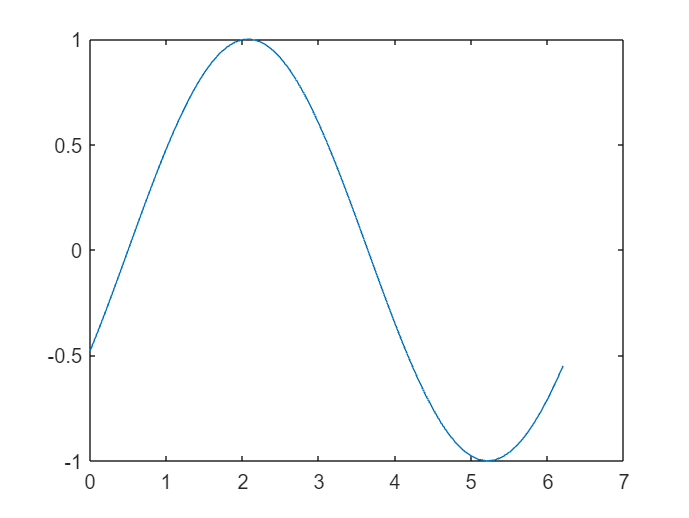

x = 0:0.1:2*pi;
y = sin(x - 0.5);
plot(x,y)

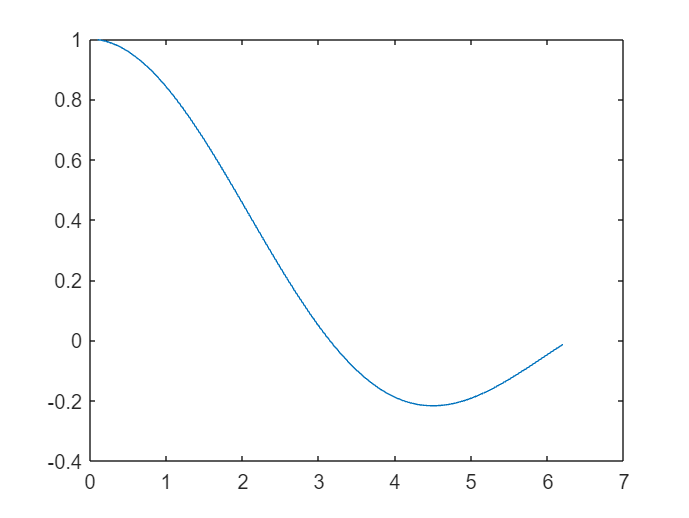

z = sin(x)./x;
plot(x,z)

b) y = e^x log(x) in [0; 1].

x = 0:0.05:1;
y = exp(x).*log(x)

y =       -Inf   -3.1493   -2.5448   -2.2041   -1.9658   -1.7800   -1.6252   -1.4898   -1.3669   -1.2523   -1.1428   -1.0362   -0.9308   -0.8252   -0.7183   -0.6090   -0.4966   -0.3802   -0.2591   -0.1326         0


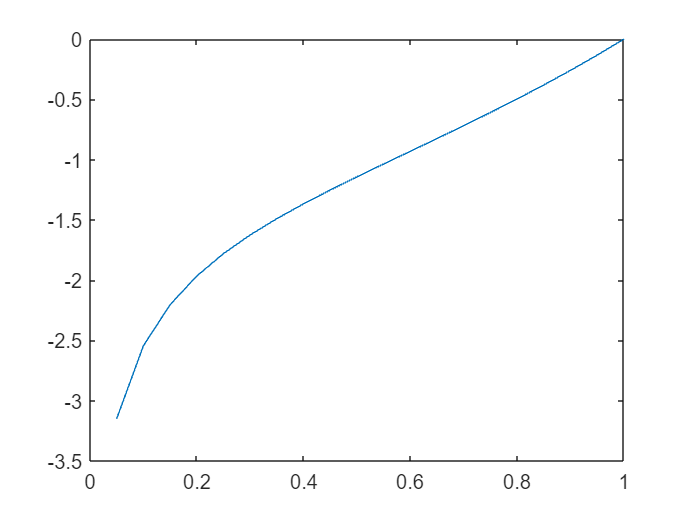

plot(x,y)

Question 2.2

Write a program that adds the numbers 1 through 100, and save it as a MATLAB script.

%run("num.m")

Question 2.3

Write a program that adds the even numbers between 1 and 100, and save it as a MATLAB script.

%run("even.m")

Question 2.4

Write down a MATLAB script for finding the maximum of three given numbers a, b and c. Test

the code by taking a = 1; b = -1 and c = 2.

a = 1; b = -1; c = 2;
max([a b c])

ans = 2

Question 2.5

Write the MATLAB script to find the first integer n for which n! (the factorial of n) is a 100-digit number.

sum = 0;
i = 0;
while sum<100
    i = i + 1;
    sum = sum + log10(i);
end
disp(i)

    70



Question 2.6

Write down the MATLAB script for computing a root of a given function f(x) using Newton-Raphson's method. The script takes as input the function f(x), it's derivative f'(x), the starting point x0, error e and number of iterations.

%run("Newton.m")

Question 2.7

Write down the MATLAB script for computing a root of a given function f(x) using Secant method. The script takes as input the function f(x), it's derivative f0(x), the starting points xl and xu, error e and number of iterations.

Use the above two scripts to solve the following problems.

%run("Secant.m")

Question 2.8

Use Newton's method to find solutions accurate within 10^-3 for the following problems. Use the mid point of the intervals as the starting point.

x3 - 2x2 - 5 = 0 on the interval [1, 4]

a = @(x) x^3 - 2*x^2 - 5;
b = @(x) 3*x^2 - 4*x;
root = Newton(a,b,2.5,0.001,10000);

Unrecognized function or variable 'Newton'.

disp(root)

x cos(x) = 0 on (0,pi)

a = @(x) x*cos(x);
b = @(x) cos(x) - x*sin(x);
root = Newton(a,b,pi/2,0.001,10000)
disp(root)

Question 2.9

Apply Newton's method to find the approximation of the root of x = tan x, starting with initial guess x0 = 4 and x0 = 4.6. Compare the results obtained from these two initial guesses. Does the method converge?

a = @(x) x - tan(x);
b = @(x) 1 - sec(x);
root = Newton(a,b,4,0.001,10000);

    2.8766

    1.3305

    0.4714

    0.1583

    0.0528

    0.0176

    0.0059

    0.0020

   6.5214e-04

   2.1738e-04



root2 = Newton(a,b,4.6,0.001,10000);

    5.0296

    8.6905

    4.6033

    5.0479

    8.9341

    4.4967

    4.5087

    4.5645

    4.8404

    6.6860

   78.6357

   39.4564

   32.4553

   64.0577

   95.3616

  169.0489

  980.1290

   8.5273e+05

   1.6427e+06

   8.9672e+05

   4.8212e+05

   4.4099e+05

   8.5087e+06

   4.3074e+06

   1.1612e+08

   1.5527e+09

   8.4651e+08

   4.4161e+09

   2.8083e+09

   2.7721e+09

   1.5871e+09

   2.2918e+09

   1.4117e+09

   1.7556e+09

   1.0417e+09

   6.7173e+08

   3.3856e+08

   3.9538e+08

   3.8628e+08

   2.2683e+08

   3.1782e+08

   3.4401e+10

   2.4248e+10

   4.0761e+10

   1.6471e+11

   2.6232e+12

   8.0720e+12

   7.3003e+12

   3.8171e+12

   2.2911e+12

   1.2695e+12

   1.3829e+12

   8.7072e+11

   5.5209e+11

   3.8841e+11

   2.9590e+11

   3.7936e+11

   2.1406e+11

   1.2841e+11

   3.1389e+11

   2.2024e+11

   1.2478e+11

   1.6852e+11

   1.2198e+12

   2.5231e+13

   7.1475e+15

   2.5750e+16

   2.0975e+17

   1.0520e+17

   4.9628e+21

 

disp(root)

   2.1738e-04



disp(root2)

   NaN



Question 2.10

f(x) = x - 2 + log(x) has a root near x = 1.5. Use the Newton Raphson formula to obtain the better estimate upto error of 0.05%.

a = @(x) x - 2 + log(x);
b = @(x) 1 + 1/x;
root = Newton(a,b,1.5,0.0005,10000)
disp(root)

Question 2.11

Obtain an estimation (accurate till 4 decimal point) of the point of intersection of the curves y = x - 1 and y = cos x.

a = @(x) x - 1 - cos(x);
b = @(x) 1 + sin(x);
root = Newton(a,b,0.5,0.0001,100000);
disp(root)

Question 2.12

Apply Newton's method to the function

f(x) =

x2/3 if x >= 0

-x2/3 if x < 0

with the root x0 = 0. What is the behavior of the iterates? Do they con- verge, if yes, at what order?

a = @(x) abs(x^(2/3));
b = @(x) 2/(3*x^(1/3));
Newton(a,b,0.1,0.0001,10000)

Question 2.13

Use Newton's method and secant method for finding the approximations of the two zeros, one in [-1, 0] and other in [0, 1] to within 10-3 accuracy of f(x) = 230x4 +18x3 +9x2 - 221x -9.

Use the end points of the interval as initial guesses for the secant method and the midpoint for Newton's method.

f = @(x) 230*x^4 + 18*x^3 + 9*x^2 - 221*x - 9;
deriv = @(x) 920*x^3 + 54*x^2 + 18*x - 221;

Newton(f,deriv,-0.5,0.001,10000)
Secant(f,-0.5,-0.6,0.001,10000)

Newton(f,deriv,10,0.001,10000)
Secant(f,10,10.1,0.001,10000)

Question 2.14

Redo Problem 2.8 using Secant method.

f1 = @(x) x^3 - 2*x^2 - 5;
f2 = @(x) x*cos(x);
Secant(f1,2.5,2.6,0.001,10000)
Secant(f2,pi/2,pi/2-1,0.001,10000)

Question 2.15

Solve the Problem 2.8 using MATLAB inbuilt function "\fzero" and compare the results obtained with the bisection and secant method.

fzero(@(x) x^3-2*x^2-5,[1 10])
fzero(@cos, [0,2]) %Range needed
fzero(@(x) x*cos(x),pi/2)

## Tutorial sheet 1

11. Use Newton’s method to approximate, to within 10−3, the value of x that produces the point on the graph of y = x2 that is closest to (1, 0) :

Hint: Minimize [d(x)]2, where d(x) represents the distance from (x, x2) to (1, 0)

d(x) = (x-1)^2 + (x^2)^2 = x4 + x2 - 2x + 1

d'(x) = 4x3 + 2x - 2

d''(x) = 12x2 + 2

f = @(x) x^2;
a = @(x) x^4 + x^2 - 2*x + 1;
b = @(x) 4*x^3 + 2*x - 2;
c = @(x) 12*x^2 + 2;

root1 = Newton(b,c,1,0.001,10000);
disp(root1);
    
x = (-1:0.01:1);
y = x.*x;
plot(x,y)
hold
plot(0,1,"ro")
plot(root1,f(root1),"ro");

Make derivative of distance = 0.